hovOLA = 'C:\Users\maran\MATLAB Drive\positionControl\parrotMinidroneCompetition4\pCRhovOLA.csv'

hovOLA = 'C:\Users\maran\MATLAB Drive\positionControl\parrotMinidroneCompetition4\pCRhovOLA.csv'


M = csvread(hovOLA)

M =          0    0.0460
    0.2000    0.0944
    0.4000    0.3170
    0.6000    0.7382
    0.8000    0.9395
    1.0000    1.0125
    1.2000    1.0475
    1.4000    1.0705
    1.6000    1.0901
    1.8000    1.1048



x = M(:,1)

x =          0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000
    1.2000
    1.4000
    1.6000
    1.8000


y = M(:,2)

y =     0.0460
    0.0944
    0.3170
    0.7382
    0.9395
    1.0125
    1.0475
    1.0705
    1.0901
    1.1048


xx = x/5

xx =          0
    0.0400
    0.0800
    0.1200
    0.1600
    0.2000
    0.2400
    0.2800
    0.3200
    0.3600



S = stepinfo(M)

S = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


ss = stepinfo(y,xx)

ss = struct with fields:
        RiseTime: 0.1380
    SettlingTime: 1.0543
     SettlingMin: 1.0125
     SettlingMax: 1.1377
       Overshoot: 3.8142
      Undershoot: 0
            Peak: 1.1377
        PeakTime: 0.5200



rise = S(2,1).RiseTime

rise = 3.4503

sTime = S(2,1).SettlingTime

sTime = 27.3579

sMin = S(2,1).SettlingMin

sMin = 1.0125

sMax = S(2,1).SettlingMax

sMax = 1.1377

oS = S(2,1).Overshoot

oS = 3.8142

peak = S(2,1).Peak

peak = 1.1377

peakTime = S(2,1).PeakTime

peakTime = 14


timeM = [rise; sTime; sMin; sMax; oS]

timeM =     3.4503
   27.3579
    1.0125
    1.1377
    3.8142


timM = timeM*5

timM =    17.2515
  136.7893
    5.0625
    5.6885
   19.0711



sourceRowNum = round(timM(1,:))         

sourceRowNum = 17

riseV = M(sourceRowNum,:)

riseV =     3.2000    1.1355



sourceRowNum = round(timM(2,:))         

sourceRowNum = 137

sTimeV = M(sourceRowNum,:)

sTimeV =    27.2000    1.0943



sourceRowNum = round(timM(3,:))         

sourceRowNum = 5

sMinV = M(sourceRowNum,:)

sMinV =     0.8000    0.9395



sourceRowNum = round(timM(4,:))         

sourceRowNum = 6

sMaxV = M(sourceRowNum,:)

sMaxV =     1.0000    1.0125



sourceRowNum = round(timM(5,:))         

sourceRowNum = 19

overshootV = M(sourceRowNum,:)

overshootV =     3.6000    1.1372




peakTime = peakTime/5

peakTime = 2.8000


stepData = [riseV; sMinV; peakTime, peak; sTimeV(:,1)/5 ,sTimeV(:,2)]

stepData =     3.2000    1.1355
    0.8000    0.9395
    2.8000    1.1377
    5.4400    1.0943


t = table(stepData)

t = 4×1 table
       stepData    
    _______________

     3.2     1.1355
     0.8    0.93945
     2.8     1.1377
    5.44     1.0943



%sT = num2str(sTime,'%.1d')

hold on
plot(x,y)
plot(stepData(:,1),stepData(:,2),'+','MarkerSize',12)
xvvv = xline(sTime/5,'--m',{'Settling Time'});
%xvv = xline(sTime, '--m', {'Settling Time'})

xv = xline(peakTime,'-.g',{'PeakTime'})

xv =   ConstantLine (PeakTime) with properties:

    InterceptAxis: 'x'
            Value: 2.8000
            Color: [0 1 0]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: {'PeakTime'}
      DisplayName: ''

  Show all properties


xv.LabelVerticalAlignment = 'middle';
%xvv.LabelVerticalAlignment = 'middle';
xvvv.LabelVerticalAlignment = 'middle';
yline(peak,'-.g',{'Peak'})

ans =   ConstantLine (Peak) with properties:

    InterceptAxis: 'y'
            Value: 1.1377
            Color: [0 1 0]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: {'Peak'}
      DisplayName: ''

  Show all properties


yline(sMinV(:,2),'-.c',{'Rise Time'})

ans =   ConstantLine (Rise Time) with properties:

    InterceptAxis: 'y'
            Value: 0.9395
            Color: [0 1 1]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: {'Rise Time'}
      DisplayName: ''

  Show all properties


xline(sMinV(:,1),'-.c')

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 0.8000
            Color: [0 1 1]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


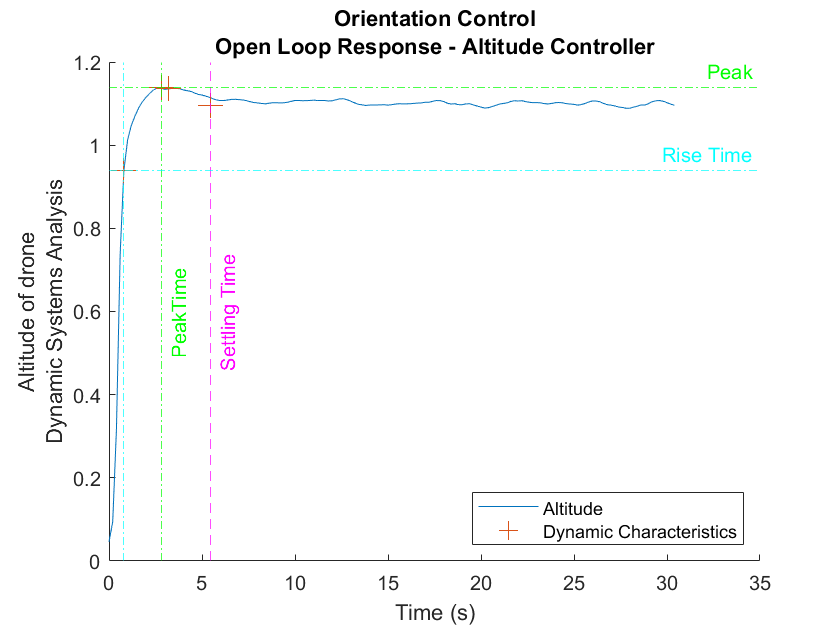


xlabel('Time (s)');
ylabel({'Altitude of drone';'Dynamic Systems Analysis'})
title({'Orientation Control';'Open Loop Response - Altitude Controller'})
legend({'Altitude'; 'Dynamic Characteristics'},'Location','southeast')


% twocolmat = rand(100,2)
% idx = twocolmat(:,2) %>= 0.2
% idx*1000
% k = find(idx == 5752)
% %col2vals = twocolmat(idx,2)